clc; clear; close all;

% Parámetros del sistema
V_pfr = 3000; % Volumen del PFR en litros
n = 5; % Número de CSTR en serie
V_cstr = V_pfr / n; % Volumen de cada CSTR

% Constantes de reacción
k = 0.1; % Constante cinética de primer orden

% Flujo de entrada
F_A = 1354458; % Flujo inicial de A en mol/h
F_B = 145120; % Flujo inicial de B en mol/h

% Matrices de estado para n CSTR en serie
A = -k * eye(n);
B = (1/V_cstr) * ones(n,1);
C = ones(1,n); % Ajuste de la salida para compatibilidad
D = 0;

% Crear función de transferencia del sistema
sys = ss(A, B, C, D);
G = tf(sys);

% Mostrar función de transferencia sin control
disp('Función de transferencia sin control:');

Función de transferencia sin control:


G

G =
 
  0.008333 s^4 + 0.003333 s^3 + 0.0005 s^2 + 3.333e-05 s + 8.333e-07
  ------------------------------------------------------------------
        s^5 + 0.5 s^4 + 0.1 s^3 + 0.01 s^2 + 0.0005 s + 1e-05
 
Continuous-time transfer function.
Model Properties


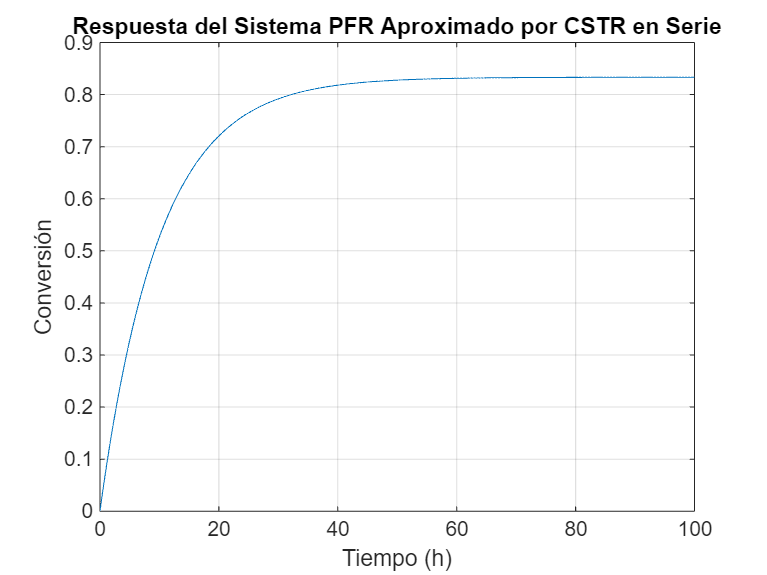


% Representación en el tiempo
t = linspace(0, 100, 1000); % Tiempo en horas
u = ones(size(t)); % Entrada escalón
[y, t_out] = lsim(G, u, t);

% Gráfica de respuesta en el tiempo
figure;
plot(t_out, y*10);
xlabel('Tiempo (h)'); ylabel('Conversión');
title('Respuesta del Sistema PFR Aproximado por CSTR en Serie');
grid on;

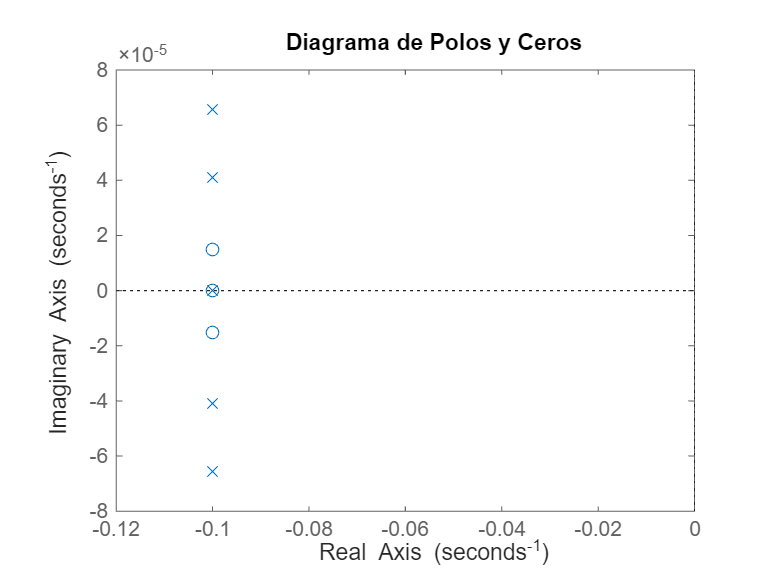


% Diagrama de polos y ceros
figure;
pzmap(G);
title('Diagrama de Polos y Ceros');


% Sintonización del control PID
Kp = 100; Ki = 25; Kd = 0.1; % Ajuste para estabilización en 0.8
PID = pid(Kp, Ki, Kd);
G_PID = feedback(PID * G, 1, -1); % Ajuste para compatibilidad de tamaños

% Mostrar función de transferencia con control PID
disp('Función de transferencia con control PID:');

Función de transferencia con control PID:


G_PID

G_PID =
 
  0.0008333 s^6 + 0.8337 s^5 + 0.5417 s^4 + 0.1333 s^3 + 0.01583 s^2 + 0.0009167 s + 2.083e-05
  --------------------------------------------------------------------------------------------
    1.001 s^6 + 1.334 s^5 + 0.6417 s^4 + 0.1433 s^3 + 0.01633 s^2 + 0.0009267 s + 2.083e-05
 
Continuous-time transfer function.
Model Pro

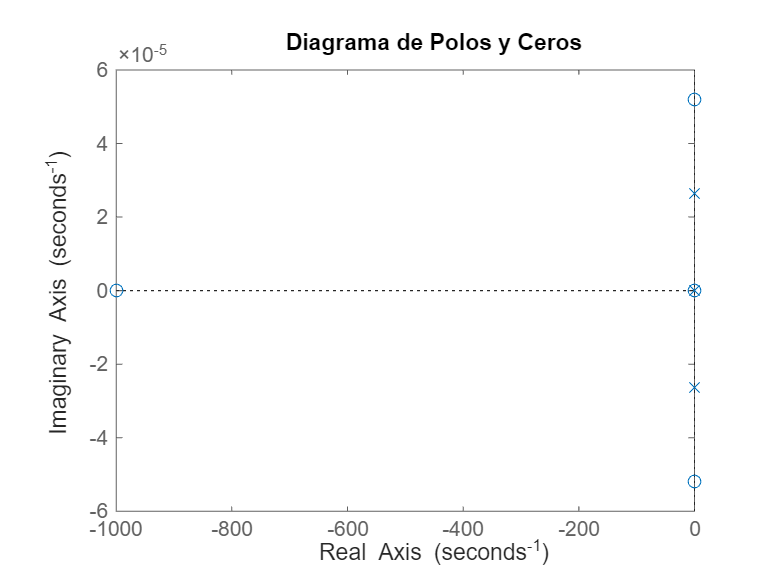

pzmap(G_PID);
title('Diagrama de Polos y Ceros');

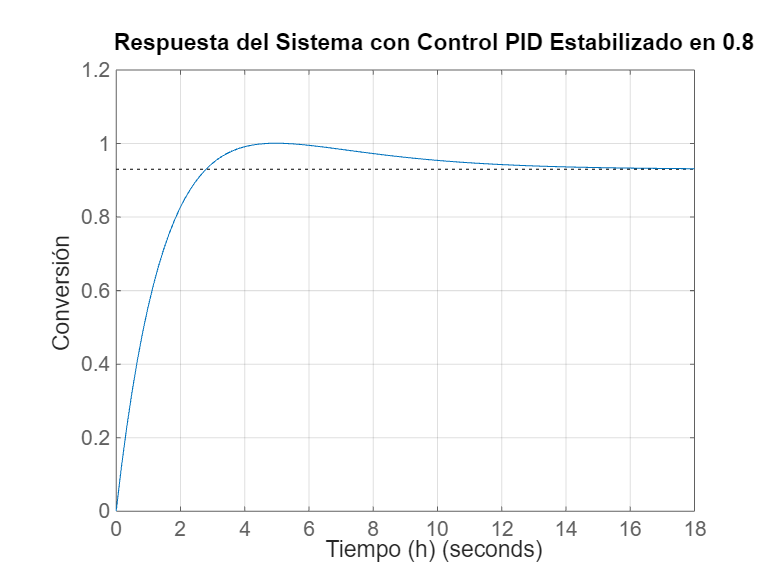


% Respuesta del sistema en lazo cerrado
y_target = 0.93; % Objetivo de estabilización
figure;
step(y_target * G_PID);
title('Respuesta del Sistema con Control PID Estabilizado en 0.8');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;

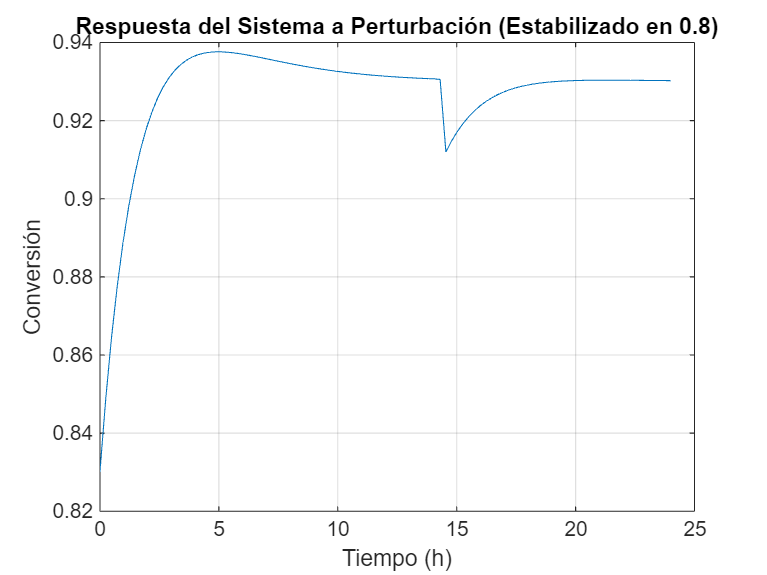


% Inserción de perturbación
t = linspace(0, 24, 100);
t_pert = t(60); % Tiempo en horas en que ocurre la perturbación
mag_pert = 0.1; % Magnitud de la perturbación
delta_u = zeros(size(t));
delta_u(t ~= t_pert) = mag_pert;

[y_pert, t_out] = lsim(G_PID, delta_u, t);

y_pert = y_pert - mag_pert;
figure;
plot(t_out, y_pert + y_target);
title('Respuesta del Sistema a Perturbación (Estabilizado en 0.8)');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;